clear, clc, close all, format compact, format long 
load currentState.mat
matrix = permute(InfraredSensorArray, [3,1,2])

matrix = matrix(:,:,1) =
   1.964809384164223   1.974584555229717   2.258064516129032   2.033235581622678   1.515151515151515   1.168132942326491   0.752688172043011   0.591397849462366   0.522971652003910   0.508308895405670   0.498533724340176   0.449657869012708   0.425219941348974   0.386119257086999   0.361681329423265   0.337243401759531
   1.964809384164223   1.959921798631476   2.214076246334311   2.033235581622678   1.510263929618768   1.168132942326491   0.909090909090909   0.610948191593353   0.542521994134897   0.503421309872923   0.498533724340176   0.454545454545455   0.425219941348974   0.371456500488759   0.361681329423265   0.337243401759531
   1.964809384164223   1.935483870967742   2.199413489736070   2.043010752688172   1.510263929618768   1.173020527859238   0.752688172043011   0.596285434995112   0.620723362658847   0.508308895405670   0.498533724340176   0.444770283479961   0.415444770283480   0.381231671554252   0.361681329423265   0.342130987292278
   1.9599217

beam1 = matrix(:,:,1)

beam1 =    1.964809384164223   1.974584555229717   2.258064516129032   2.033235581622678   1.515151515151515   1.168132942326491   0.752688172043011   0.591397849462366   0.522971652003910   0.508308895405670   0.498533724340176   0.449657869012708   0.425219941348974   0.386119257086999   0.361681329423265   0.337243401759531
   1.964809384164223   1.959921798631476   2.214076246334311   2.033235581622678   1.510263929618768   1.168132942326491   0.909090909090909   0.610948191593353   0.542521994134897   0.503421309872923   0.498533724340176   0.454545454545455   0.425219941348974   0.371456500488759   0.361681329423265   0.337243401759531
   1.964809384164223   1.935483870967742   2.199413489736070   2.043010752688172   1.510263929618768   1.173020527859238   0.752688172043011   0.596285434995112   0.620723362658847   0.508308895405670   0.498533724340176   0.444770283479961   0.415444770283480   0.381231671554252   0.361681329423265   0.342130987292278
   1.959921798631476   1.9696

beam1rs = reshape(beam1, [1600, 1])

beam1rs =    1.964809384164223
   1.964809384164223
   1.964809384164223
   1.959921798631476
   1.959921798631476
   1.964809384164223
   1.959921798631476
   1.959921798631476
   1.964809384164223
   1.989247311827957


distanceArray = [25, 50, 75, 100, 150, 200, 300, 400, 500, 600, 700, 850, 1000, 1150, 1300, 1500];
xValue = repmat(distanceArray,[100,1])

xValue =           25          50          75         100         150         200         300         400         500         600         700         850        1000        1150        1300        1500
          25          50          75         100         150         200         300         400         500         600         700         850        1000        1150        1300        1500
          25          50          75         100         150         200         300         400         500         600         700         850        1000        1150        1300        1500
          25          50          75         100         150         200         300         400         500         600         700         850        1000        1150        1300        1500
          25          50          75         100         150         200         300         400         500         600         700         850        1000        1150        1300        1500
          25          50  

xValuers = reshape(xValue, [1600, 1])

xValuers =     25
    25
    25
    25
    25
    25
    25
    25
    25
    25


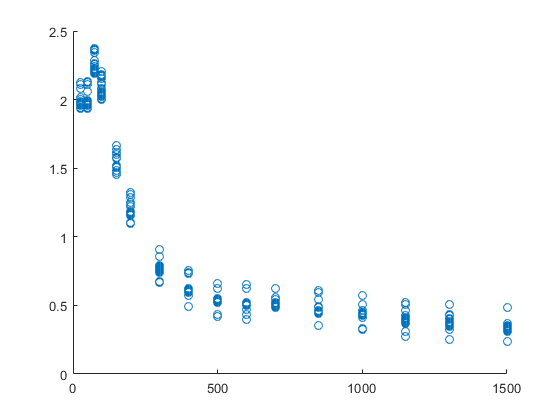

scatter(xValuers, beam1rs)

% enter data
x = xValuers;
y = beam1rs; 

% calculate coefficients a and b
n = length(x);
y2 = log(y);
j = sum(x);
k = sum(y2);
l = sum(x.^2);
m = sum(y2.^2);
r2 = sum(x .* y2);
b = (n * r2 - k * j) / (n * l - j^2)

b =   -0.001307397931801

a = exp((k-b*j)/n) 

a =    1.607540556037701


% calculate coeff. of determination, coeff. of correlation
% and standard error of estimate
c = b * (r2 - j * k / n);
d = m - k^2 / n;
f = d - c;
cf_dt = c/d

cf_dt =    0.798317938315193

corr = sqrt(cf_dt)

corr =    0.893486395148349

std_err = sqrt(f / (n - 2)) 

std_err =    0.306024278111276

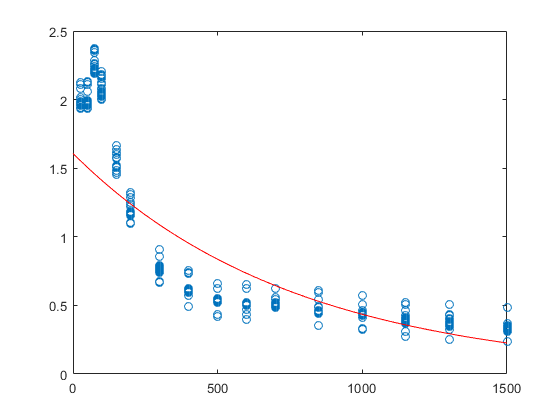



x = linspace(0,1500,1500);
plot(xValuers, beam1rs, 'o', x, a * exp(b * x), '-r')